## Choose chromosome

chromosome_of_interest = 'chr5';

filename = strcat('Human Genome/', chromosome_of_interest, '.fa');
reads = fastaread(filename);
chrm_sequence = reads.Sequence;
chrm_sequence = upper(string(chrm_sequence));

## Choose transcription factor

can search for common TFs in [find_popular_TF.mlx](find_popular_TF.mlx_)

TF_of_interest = 'CTCF';

### Get the PWM for chosen TF

[pwm_matrix, TF_binding_length] = getPWM(TF_of_interest);

pwmatrix =     0.0540    0.0240    0.0680    0.0420         0    0.2620    0.0040         0    0.0320    0.2660    0.0200    0.0800    0.0100    0.0260    0.1260
    0.3180    0.6460    0.0420    0.7900    0.9940    0.6660    0.6180    0.9980    0.0640    0.0900    0.3440    0.1940    0.0020    0.0660    0.5940
    0.5660    0.0240    0.7920    0.0620         0    0.0460    0.0020    0.0020    0.0080    0.5640    0.6200    0.0440    0.9760    0.8400    0.0740
    0.0620    0.3060    0.0980    0.1060    0.0060    0.0260    0.3760         0    0.8960    0.0800    0.0160    0.6820    0.0120    0.0680    0.2060


TF_binding_length

TF_binding_length = 15

### Get the actual binding positions for TF

TF_binding_pos = load("factorbookMotifPos.mat")

TF_binding_pos = struct with fields:
    data: [7×2366151 string]


TF_names_row = TF_binding_pos.data(5,:);
true_binding_pos = TF_binding_pos.data(:, TF_names_row == TF_of_interest);
true_binding_pos = true_binding_pos';
chromosome_col = true_binding_pos(:,2);
true_binding_pos = true_binding_pos(chromosome_col == chromosome_of_interest, :);
true_binding_pos = true_binding_pos(:, [3, 6, 7])

true_binding_pos = 7471×3 string array
    "13272"     "3.72"    "+"
    "13502"     "2.13"    "-"
    "21827"     "2.99"    "-"
    "42450"     "2.6"     "-"
    "42460"     "1.98"    "-"
    "53934"     "3.58"    "-"
    "77739"     "2.76"    "-"
    "78775"     "2.49"    "-"
    "78852"     "3.39"    "-"
    "78882"     "2.28"    "+"
    "81861"     "1.52"    "+"
    "106783"    "2.4"     "+"
    "146054"    "1.94"    "+"
    "146056"    "3.26"    "-"
    "188876"    "2.16"    "-"
    "191820"    "2.09"    "+"
    "192040"    "1.5"     "-"
    "195830"    "1.43"    "-"
    "195863"    "1.5"     "-"
    "195980"    "2.4"     "-"
    "195995"    "2.16"    "+"
    "196052"    "1.61"    "-"
    "197303"    "2.05"    "-"
    "215878"    "2.36"    "-"
    "218075"    "2.3"     "+"
    "218788"    "1.67"    "+"
    "218991"    "1.53"    "-"
    "256664"    "2"       "+"
    "308850"    "2.04"    "-"
    "309111"    "2.77"    "+"


## Get Actual Positions

actual_positions = repmat([0], num_TFs, 2);
num_TFs = length(true_binding_pos);

loading = waitbar(0,'Please wait...');

for i=1:num_TFs
% for i=1:10
    r = i/num_TFs;
    waitbar(r,loading,string(r));
    
    start = true_binding_pos(i, 1);
    strand = true_binding_pos(i, 3);
    start = str2double(start);

    actual_positions(i, 1) = start+1;
    
    if strand == "+"
        actual_positions(i, 2) = 1;
    else 
        actual_positions(i, 2) = 0;
    end

end
close(loading);

actual_positions

actual_positions =        13273           1
       13503           0
       21828           0
       42451           0
       42461           0
       53935           0
       77740           0
       78776           0
       78853           0
       78883           1


## Predict Positions for PWM

threshold = -20

threshold = -20

positions = predict_positions(chrm_sequence, chromosome_of_interest, pwm_matrix, TF_binding_length, threshold);

positions

positions =        13214           1         -17
       13273           1          -8
       13275           0         -19
       13480           0         -15
       13503           0         -13
       21669           1         -19
       21828           0         -10
       42387           1         -19
       42451           0         -12
       42461           0         -15


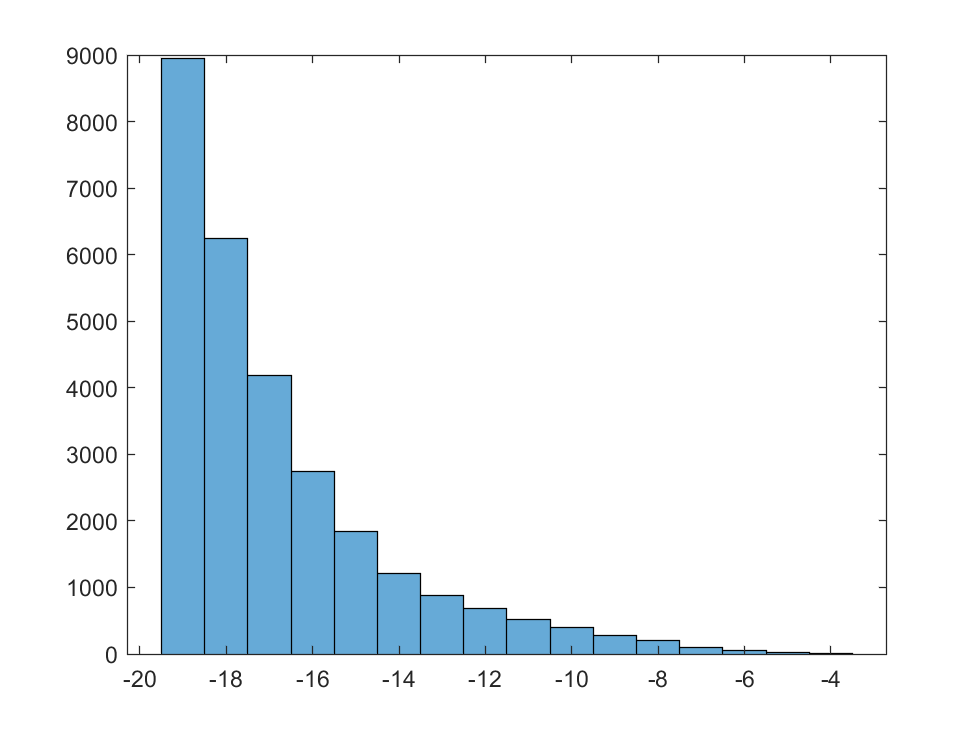

histogram(positions(:, 3))

## Get all false sequences

padding = 10; % extra bases on sides of binding regions

success = false;

false_sequences = [];

loading = waitbar(0,'Please wait...');

for k=1:length(positions)
% for k=1:200
    r = k/length(positions);
    waitbar(r,loading,string(r));
    for i=1:length(actual_positions)
        if positions(k,1) == actual_positions(i, 1) && positions(k, 2) == actual_positions(i, 2)
            success= true;
            break; 
        end
    end
    if success == false
        start = positions(k, 1);
        if positions(k, 2) == 1
            r = extractBetween(chrm_sequence,start-padding,start+TF_binding_length+padding-1);
            false_sequences = [false_sequences; r];
        else
            r = extractBetween(chrm_sequence,start-padding,start+TF_binding_length+padding-1);
            r = reverse(r);
            r = convert_negative_strand(r);
            false_sequences = [false_sequences; r];
        end
    end
    success = false;
end
close(loading);

false_sequences = cellstr(false_sequences)

false_sequences = 24245×1 cell array
    {'CCCGTTTCGGGCGCCCCGTGCTTGGAGCCGGGAAC'}
    {'GTTGCACTAGTCGCCAGCAGGGGGCAAACTGGCAC'}
    {'CCATGATTGTGAGGCCCCTGCAGCCATGTGGAACT'}
    {'GTGCTTTTTTCCAACATCTCCAGTCTTGCATTATT'}
    {'GAGGAATAACGTGTCCCGAACTGGGAACCCTTCAC'}
    {'CATGTCCTGGCCTTCCCCAGCAGTCCCCTGGAGCC'}
    {'TCTAGGCCCTCTTCCATGTCCTGGCCTTCCCCAGC'}
    {'CAAAATTGGTCCACCCTCTCCCAGGTAATCCTGGC'}
    {'TTATCATTTATTCCCACCTAGTGTGTGAGTGGTTT'}
    {'GCAGAGAGAGTTCCCATCTTGAGGACTGGAGCTCT'}
    {'TAAGCTCCTTGTGACCTCTACCTTAGGTAAAAGTA'}
    {'TGGCCTGGGAGCCTCCTCTGCCAACCCATTTCCTC'}
    {'GTCCTGTTGGCTGCCCTCAGGTTCTGTGAGTGGGC'}
    {'ATCCTGTCCCTCTGCATCTAGGGCTGCCTCGAGGT'}
    {'GCATCTAGGGCTGCCTCGAGGTGGCTCTGTTCACC'}
    {'AGGTGGCTCTGTTCACCCTGGAGGAGGCCAATGCT'}
    {'CCCCAAGCATTGGCCTCCTCCAGGGTGAACAGAGC'}
    {'GCCTTGGGTGCTGCCCACTAGGGGGTGCGTGGGGG'}
    {'CGCTGACTGCTTTACCCCTAGCTGCCCTCCTTAGG'}
    {'TTACCCCTAGCTGCCCTCCTTAGGCTGCCCTCCTT'}
    {'CCCTCCTTGACCCTCCTCTGCTGATCACCATTTCT'}
    {'CATCACAGCTTTGCCACCTTTTGCCCTGTAAGA

strlength(false_sequences(1, 1))

ans = 35

filename = strcat('false_sequences_', chromosome_of_interest, '.mat')

filename = 'false_sequences_chr5.mat'

save(filename, "false_sequences")

seq1 = load("false_sequences_chr1")

seq1 = struct with fields:
    false_sequences: {53773×1 cell}


seq2 = load("false_sequences_chr2")

seq2 = struct with fields:
    false_sequences: {36171×1 cell}


seq3 = load("false_sequences_chr3")

seq3 = struct with fields:
    false_sequences: {28032×1 cell}


seq4 = load("false_sequences_chr4")

seq4 = struct with fields:
    false_sequences: {17914×1 cell}


seq5 = load("false_sequences_chr5")

seq5 = struct with fields:
    false_sequences: {24245×1 cell}


false_sequences = [seq1.false_sequences; seq2.false_sequences;seq3.false_sequences;seq4.false_sequences;seq5.false_sequences]

false_sequences = 160135×1 cell array
    {'GATCCTTGAAGCACCCCCAAGGGCATCTTCTCAAA'}
    {'GATCCTTGAAGCGCCCCCAAGGGCATCTTCTCAAA'}
    {'CTGCCCCCACCCCGCATCCCCGGGCTCGGGTTTGC'}
    {'GAGGACGTAGCTGCCCCCACCCCGCATCCCCGGGC'}
    {'TTTCAGCTACCCTTCTTCAGCCGGCAACACACAGA'}
    {'GTCACGGAAGGCGCACCCTTGTGACGTCACAGGGG'}
    {'GGAAGAACCAGCAGCCCCCACCGCGAGTTCTGATT'}
    {'GCATGAGCGGACGCTGCCTACTGGTGGCCGGGCGG'}
    {'ACATCCCGCCCGGCCACCAGTAGGCAGCGTCCGCT'}
    {'TCTGGCCCTTGCTGCGCCCGGCGCCGAAGACCGGG'}
    {'TTGGCGCGCAGCGCCTGCTAGCGCAGAGTCTGGCC'}
    {'CGGTTGGCGCGCAGCGCCTGCTAGCGCAGAGTCTG'}
    {'CGCCAACCGGCCGGCACCTGTCGCAGAAGGTGCAA'}
    {'AGTGCGATCGGTTGCACCTTCTGCGACAGGTGCCG'}
    {'TCAATGGCCAGCGCCAGCTGCAGCCCCGGCCGCCC'}
    {'AGCGCCAGCTGCAGCCCCGGCCGCCCACTCGCCTC'}
    {'GCGCTCCACAACGCCTCCCCCAGCCAGGGCCCGGG'}
    {'CTCCACAACGCCTCCCCCAGCCAGGGCCCGGGGAT'}
    {'ATCCCCGGGAGCGTCCCCGGCTACCTGGCGCCGCT'}
    {'GGAGCGTCCCCGGCTACCTGGCGCCGCTCATCCTG'}
    {'CCCAGGATGAGCGGCGCCAGGTAGCCGGGGACGCT'}
    {'CTGGGTAGGGTCGGCCCCCTGAGGCTGCCCGG

save("false_sequences", "false_sequences")